# SysMIC M1: Assignment 7

If you need help for this assignment please make use of the [session 7 forum](https://sysmic.ac.uk/moodle/mod/forum/view.php?id=2536).

When completed please save and upload here: [http://sysmic.ac.uk/moodle/mod/assign/view.php?id=2427](http://sysmic.ac.uk/moodle/mod/assign/view.php?id=2427). 

After submission you can access model answers via the [session 7 review ](http://sysmic.ac.uk/moodle/mod/quiz/view.php?id=3233)activity.

`Name: [ ... insert your name ... ]`

## Exercise 1.4.1

([section link](https://sysmic.ac.uk/textbook/1.4-gene-expression.html#1.4.1))

1. i) Modify the MATLAB function provided that models gene expression in the presence of a repressor

to produce a function that models expression in the presence of an activator.

v_act = @(Y,K,k,n) k*K^-n/(K^-n + Y^-n);



ii) Overlay plots for the activiator and repressor cases using parameter values of K = 1, k = 10 and n = 2.

v_rep = @(Y,K,k,n) k*K^n/(K^n + Y^n);
v_act = @(Y,K,k,n) k*K^-n/(K^-n + Y^-n);
ns = [1 3 5 10 100]; 
cols = ['r' 'b' 'g' 'k' 'c'];
styl = ['r--' 'b--' 'g--' 'k--' 'c--'];
limits = [0 5];
% hold on
% for i=1:5,
%     vt_rep = @(Y) v_rep(Y,1,10,ns(i));
%     fplot(vt_rep,limits,cols(i));
%     
%     vt_act = @(Y) v_act(Y,1,10,ns(i));
%     fplot(vt_act,limits,styl(i));
% end
% axis([0 5 0 10])
% ylabel('dX/dt')
% xlabel('Y')
% legend('n=1','n=3','n=5','n=10','n=100','Location','NorthEast')
% legend('n=-1','n=-3','n=-5','n=-10','n=-100','Location','NorthEast')

% ii

figure()
vt_rep = @(Y) v_rep(Y,1,10,2);
fplot(vt_rep,limits,'g');

hold on
vt_act = @(Y) v_act(Y,1,10,2);
fplot(vt_act,limits,'b');

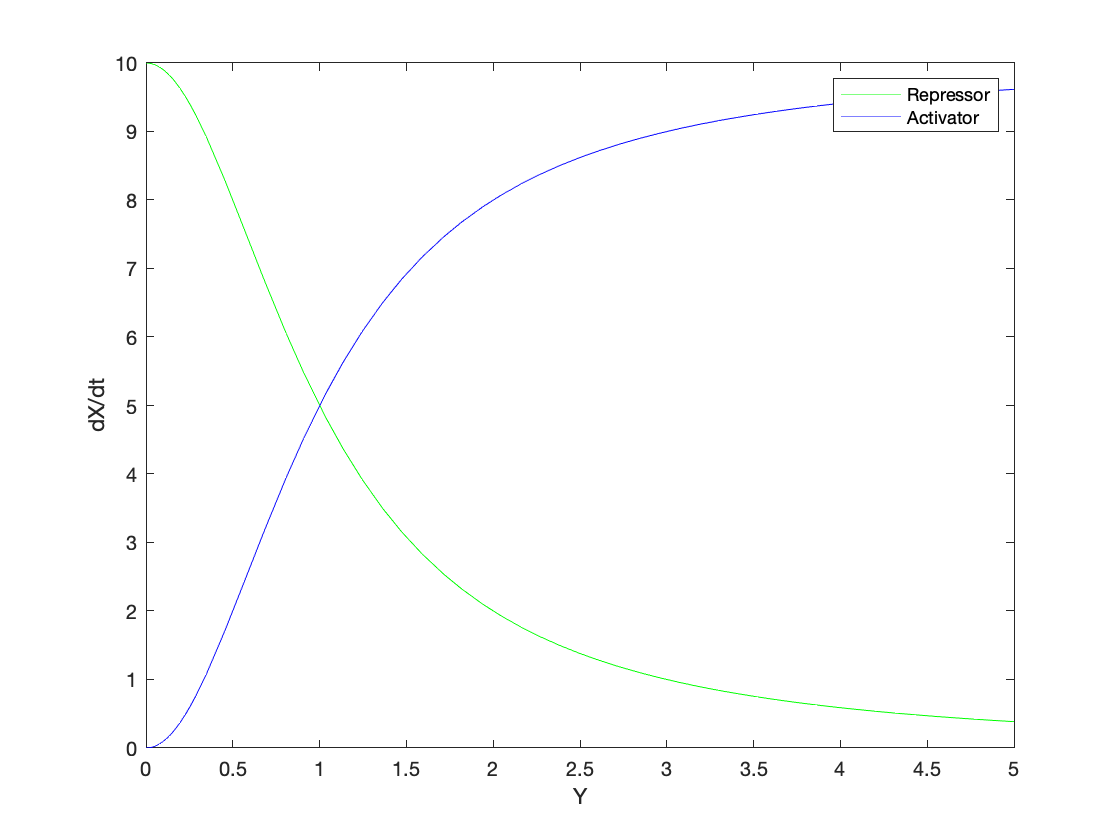


axis([0 5 0 10])
ylabel('dX/dt')
xlabel('Y')
legend('Repressor','Activator','Location','NorthEast')

iii) What do you notice about the graphs?

***Comments: The graphs are symmetrical along y = 5 and they converge at (1,5)***

## Exercise 1.4.4

([section link](https://sysmic.ac.uk/textbook/1.4-gene-expression.html#fig:lin_act_exp))

1. Look at the code which models expression of X regulated by transcription factor Y in a system described the equations:

     $\frac{\textrm{dX}}{\textrm{dt}}=\textrm{gY}-\textrm{bX}$    and    $\frac{\textrm{dY}}{\textrm{dt}}=c$

Consider a process in which $c=0\ldotp 1$, $b=1$, $g=1$ and the initial concentrations are $X_0 =0\ldotp 1$ and $Y_0 =10$

i) Modify the MATLAB code to solve the differential equations if the concentration of $Y$is now described by $\frac{\textrm{dY}}{\textrm{dt}}=-\textrm{cY}$ with initial conditions that $Y\left(t=0\right)=Y_0$ and $X\left(t=0\right)=X_0$.

syms X(t) Y(t) a b c g X0 Y0;
eqn = [ diff(X,t) == g*Y - b*X, diff(Y,t) == -c*Y ]

$$eqn(t) = \left(\begin{array}{cc} \frac{\partial }{\partial t}X\left(t\right)=g\,Y\left(t\right)-b\,X\left(t\right) & \frac{\partial }{\partial t}Y\left(t\right)=-c\,Y\left(t\right) \end{array}\right)$$

cond = [  X(0) == 0.1, Y(0) == 10 ]

$$cond = \left(\begin{array}{cc} X\left(0\right)=\frac{1}{10} & Y\left(0\right)=10 \end{array}\right)$$

r=dsolve(eqn,cond)

r = struct with fields:
    Y: [1×1 sym]
    X: [1×1 sym]


X=simplify(r.X);
Y=simplify(r.Y);
X  

$$X = \frac{10\,g\,{\mathrm{e}}^{-c\,t}}{b-c}-\frac{{\mathrm{e}}^{-b\,t}\,\left(c-b+100\,g\right)}{10\,\left(b-c\right)}$$

Y

$$Y = 10\,{\mathrm{e}}^{-c\,t}$$

ii) Plot the concentration $Y\left(t\right)$ against time.

% answer 

figure()
mY = matlabFunction(Y,'vars',[t b X0 Y0 c g])

mY = function_handle with value:
    @(t,b,X0,Y0,c,g)exp(-c.*t).*1.0e+1


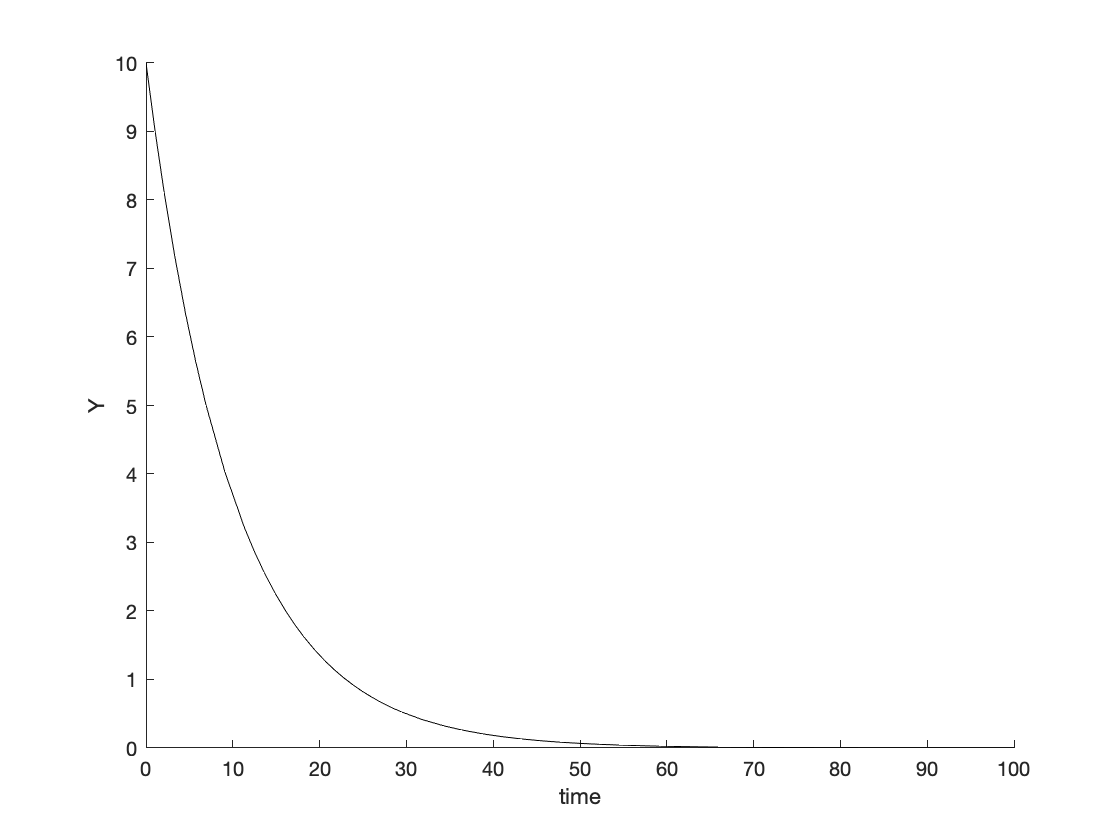

fY = @(t) mY(t, 1, 0.1, 10, 0.1, 1);
limits = [0 100];
hold on
fplot(fY, limits,'k');
% axis([0 10 0 15])
ylabel('Y')
xlabel('time')

iii) Examine the solution for $Y\left(t\right)$ you found. What type of mathematical function is it?

***Comments: It is an exponential function.***

iv) Plot $X\left(t\right)$against time.

figure()
mX = matlabFunction(X,'vars',[t b X0 Y0 c g])

mX = function_handle with value:
    @(t,b,X0,Y0,c,g)(exp(-b.*t).*(-b+c+g.*1.0e+2).*(-1.0./1.0e+1))./(b-c)+(g.*exp(-c.*t).*1.0e+1)./(b-c)


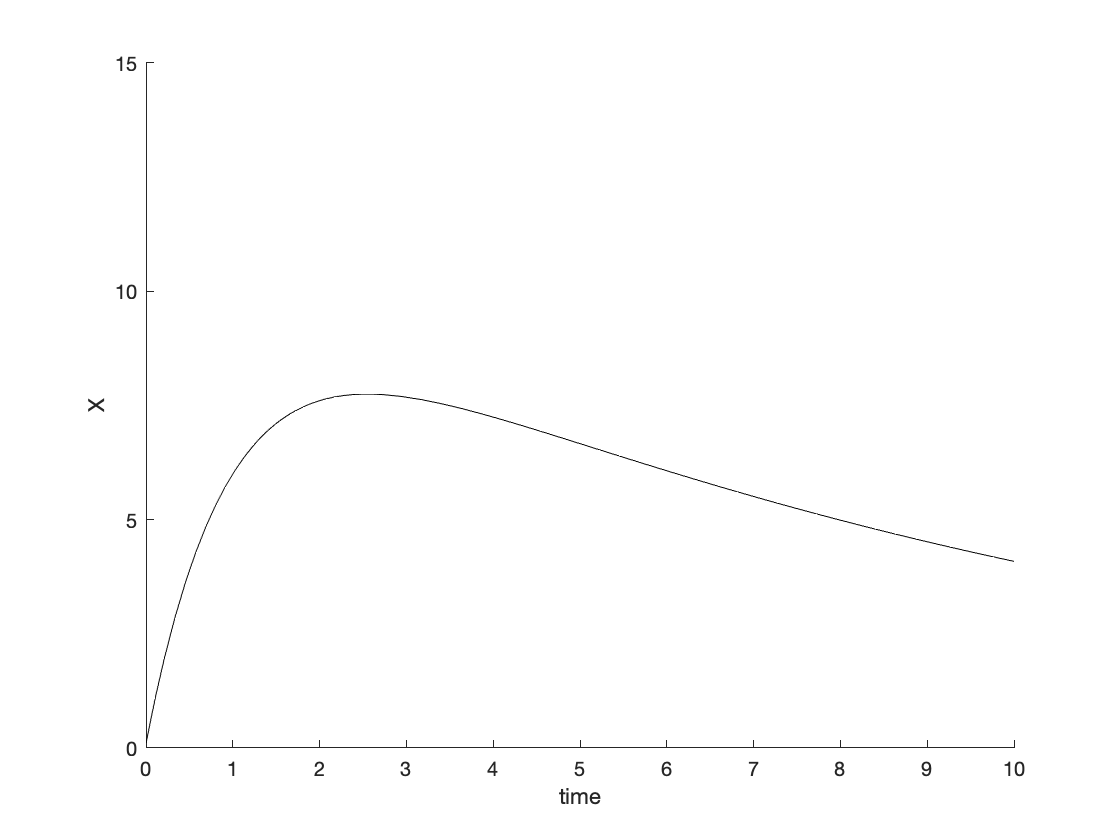

fX = @(t) mX(t, 1, 0.1, 10, 0.1, 1);
% f2 = @(t) mX(t, 1, 0, 1, 1);
% f3 = @(t) mX(t, 1, 0, 10, 1);
limits = [0 100];
hold on
fplot(fX, limits,'k');
% axis([0 10 0 15])
ylabel('X')
xlabel('time')

v) How has modifying  $\textrm{dY}/\textrm{dt}$ changed the behaviour of $X\left(t\right)$.

***Comments:***

% answer Concentration Y is no longer increasing linearly with rate c
% (dY/dt = c) and decreases at a faster rate at higher concentrations of Y
% (dY/dt = -cY). So instead of X rising exponentially with no limit, it now
% reaches a peak and steadily declines.


## **Exercise** 1.5.1

([section link](https://sysmic.ac.uk/textbook/1.5-the-genetic-toggle-switch.html#fig:toggle_ts))

1. Another toggle system can be modelled with the equations:


$$\frac{\mathrm{du}}{\mathrm{dt}}=\frac{\alpha_1 }{\mathrm{exp}\left(\beta v\;\right)}-u$$
    


$$\frac{\mathrm{dv}}{\mathrm{dt}}=\frac{\alpha_2 }{\mathrm{exp}\left(\gamma v\;\right)}-v$$


i) Modify the MATLAB code to numerically integrate these equations. Use $\alpha_2$,$\alpha_2 =10$ and $\beta ,\gamma =3$

Hint: You can then re-run the same toggle system code. Only the toggle function needs to be altered. (Remember also to change the values of $\beta$ and $\gamma$.)

*Note you may add the *`toggle`* function as a local function at the end of this live script (to avoid the need to save it in its own *`toggle.m`* file).*

% answer 


ii) Plot the concentrations of $u$ and $v$ for the cases where  $u_{0\;} ,v_0 =0\ldotp 1,1\ldotp 0$ and  $u_{0\;} ,v_0 =5\ldotp 0,4\ldotp 0$ 

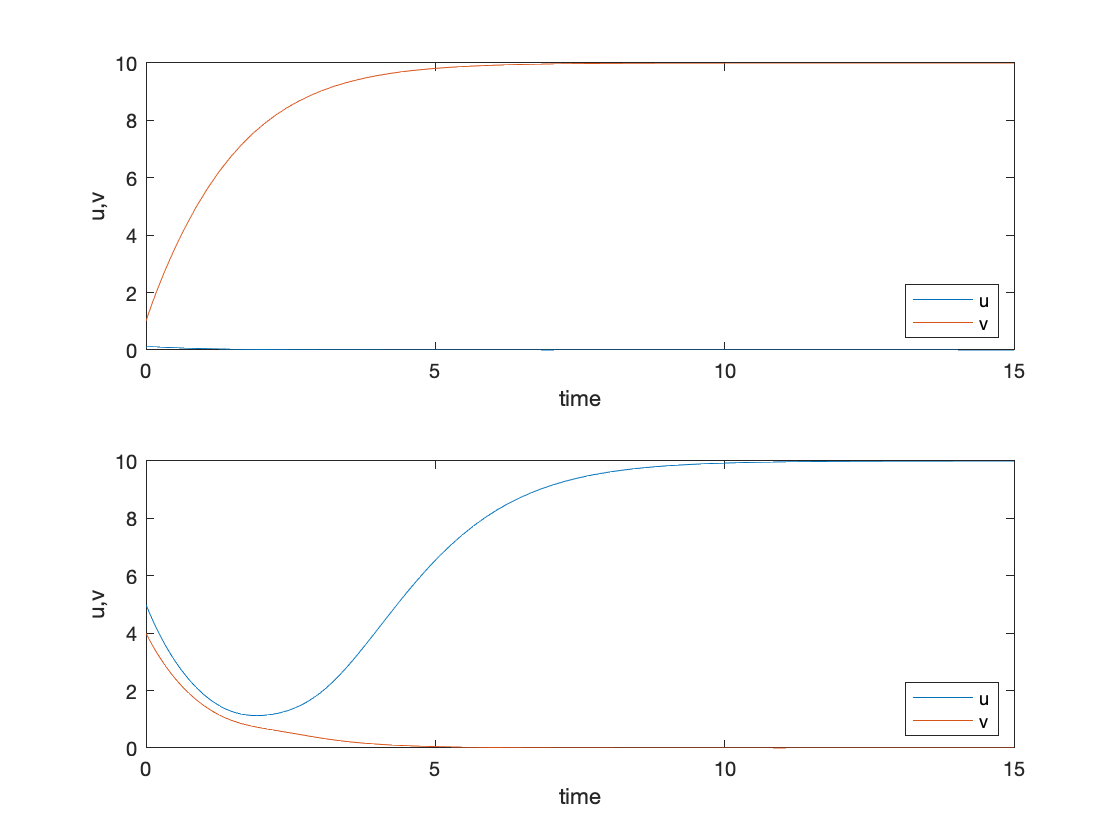

% answer 

timespan=[0 15];
figure()
subplot(2,1,1);
y0 = [0.1 1.0];
[t,y] = ode45(@toggle2,timespan,y0); 
plot(t,y)
ylabel('u,v')
xlabel('time')
legend('u','v','Location','SouthEast')
subplot(2,1,2);
y0 = [5.0 4.0];
[t,y] = ode45(@toggle2,timespan,y0);
plot(t,y)
ylabel('u,v')
xlabel('time')
legend('u','v','Location','SouthEast')

**Local functions:**

% add code for toggle function here

function ydot=toggle2(t,y)
    alpha1 = 10.0;
    alpha2 = 10.0;
    beta = 3.0;
    gamma = 3.0;
    
    du = -y(1) + alpha1/(exp(y(2)*beta));
    dv = -y(2) + alpha2/(exp(y(1)*gamma));
    
    ydot = [du; dv];
end
